# Antiderivatives

[⇦ Overview](matlab: OpenOverview)

The rates of change of variables turn up frequently when studying real-life interactions including velocity, acceleration, and current. In cases where we know the derivative and we want to determine the original function, we want to find the *antiderivative. *

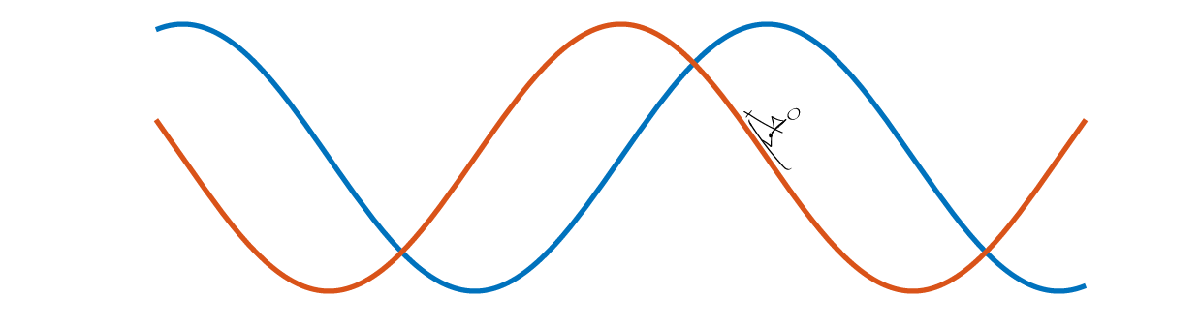

By using the knowledge of derivatives, it is possible to define an operation that will undo a derivative. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Power Rule Practice

$\displaystyle \int x^n\; dx = \frac{x^{n+1}}{n+1}+C$ for $n \neq -1$.                $(\star)$

### **Exercise 1**

Solve the integrals below in the variables given. In each case, you should identify the value of $n$ and $n+1$ as used in equation $(\star)$. Use `C` for an arbitrary constant, as required. 

a. $\displaystyle F(x) = \int x^4\; dx$                    

an = 0;         anp1 = 0;             asoln = @(x,C) x;
checkExercise1(an,anp1,asoln,4)

b. $G(t) = \displaystyle \int t^{-7.3}\; dt$

bn = 0;         bnp1 = 0;             bsoln = @(t,C) t;
checkExercise1(bn,bnp1,bsoln,-7.3)

c. $H(q) = \displaystyle \int q^{-1/7}\; dq$

cn = sym(0);      cnp1 = sym(0);      csoln = @(q,C) q;
checkExercise1(cn,cnp1,csoln,-1/7)

## **Exponential Rule**


$$\int e^{ax}\; dx = \frac{e^{ax}}{a} + C.$$
           
$$(\diamond)$$


### **Exercise 2**

Solve the integrals below in the variables given. Use `C` for an arbitrary constant, as required and identify $a$ as it is in equation $(\diamond)$ . Remember the MATLAB notation for $e^x$ is `exp(x)`.

a. $\displaystyle F(x) = \int e^{6x}\; dx$

an = 0;        asoln = @(x,C) x;
checkExercise2(an,asoln,6)

b. $\displaystyle G(t) = \int e^{-3t}\; dt$

bn = 0;        bsoln = @(t,C) t;
checkExercise2(bn,bsoln,-3)

## Logarithm Rule Practice

$\displaystyle \int \frac{1}{x}\;dx = \ln(|x|)+C$       for $x <0$ or $x>0$.

### **Exercise 3**

Solve the integrals below in the variables given. Use `C` for an arbitrary constant, as required. Remember that the MATLAB notation for $\ln(x)$ is `log(x)` and for $|x|$ is `abs(x)`.

a. $\displaystyle F(r) = \int \frac{1}{r}\; dr$

asoln = @(r,C) r;
checkExercise3(asoln,1,"ln")

b. $\displaystyle G(t) = \int \frac{-2}{t}\; dt$

bsoln = @(t,C) t;
checkExercise3(bsoln,-2,"ln")

c. $\displaystyle H(w) = \int \frac{1}{8w}\; dw$

csoln = @(w,C) w;
checkExercise3(csoln,1/8,"ln")

## Cosine Rule Practice


$$\int \cos(ax)\; dx = \frac{1}{a}\sin(ax) + C$$


### **Exercise 4**

Solve the integrals below in the variables given. Use `C` for an arbitrary constant, as required.

a. $\displaystyle F(r) = \int \cos(4r)\; dr$

asoln = @(r,C) r;
checkExercise3(asoln,4,"cos")

b. $\displaystyle G(t) = \int \cos(-9t)\; dt$

bsoln = @(t,C) t;
checkExercise3(bsoln,-9,"cos")

c. $\displaystyle H(\theta) = \int \cos\left(\frac{2\theta}{3}\right)\; d\theta$                                             Note: $\theta$ should be `theta` in the typed solution.

csoln = @(theta,C) theta;
checkExercise3(csoln,2/3,"cos")

## Sine Rule Practice


$$\int \sin(ax)\; dx = -\frac{1}{a}\cos(ax)+C.$$


### **Exercise 5**

Solve the integrals below in the variables given. Use `C` for an arbitrary constant, as required.

a. $\displaystyle F(r) = \int \sin(9r)\; dr$

asoln = @(r,C) r;
checkExercise3(asoln,9,"sin")

b. $\displaystyle G(t) = \int \sin(-2t)\; dt$

bsoln = @(t,C) t;
checkExercise3(bsoln,-2,"sin")

c. $\displaystyle H(\theta) = \int \sin\left(-\frac{\pi \theta}{2}\right)\; d\theta$               Note: The variable $\theta$ should be `theta` in the typed solution and the constant $\pi$ should be `pi`.

cinput = str2sym(" theta");
csoln = matlabFunction(cinput,Vars=[sym("theta"),sym("C")]);
checkExercise3(csoln,-pi/2,"sin")

## Practice Randomized Antiderivatives

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear errorCount totAntiProbs totAttempts adjustcount lastFive myFun varChoice
syms t r x z C                       % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totAntiProbs = 0;                    % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Antiderivative Practice.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totAntiProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = genProbType(varOpts,1);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totAntiProbs = totAntiProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totAntiProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
analyzeResults(totAntiProbs,errorCount,totAttempts,adjustCount,lastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Integrals of Functions" in the Integrals section. The app will open in a new window.

[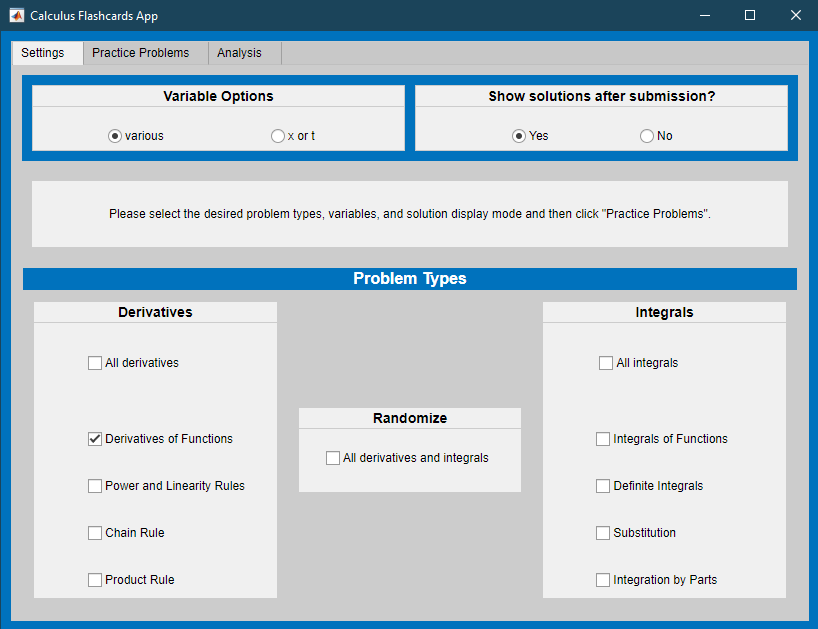](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

**Check Exercise 1**

Check that some effort has been made and give appropriate feedback.

function checkExercise1(n,np1,mysoln,nReal)
syms x C
if n == nReal
    if nReal+1 == np1
        if isAlways(diff(mysoln(x,C),x)==x^(nReal),"Unknown","false")
            if diff(mysoln(x,C),C)~=0
                disp("This solution is correct.")
            else
                disp("Although you have the correct identification of n and n+1, your answer is incorrect because it is missing +C")
            end
        else
            disp("Although you have the correct identification of n and n+1, your answer is incorrect. Please check the power rule.")
        end
    elseif np1 == 0
        disp("You have begun the problem. Please finish before submitting.")
    else
        disp("Although you have the correct identification of n, you have an incorrect value for n+1. Please check your arithmetic.")
    end
elseif n == 0 && np1 == 0 && isequal(mysoln(x,C),x)
    disp("Please attempt the problem before submitting.")
else
    disp("That is not the correct value for n. Please check your patterns and try again.")
end
end

**Check Exercise 2**

Check that some effort has been made and give appropriate feedback.

function checkExercise2(n,mysoln,nReal)
syms x C
if n == nReal
    if isAlways(diff(mysoln(x,C),x)==exp(nReal*x),"Unknown","false")
        if diff(mysoln(x,C),C)~=0
            disp("This solution is correct.")
        else
            disp("Although you have the correct identification of a, your answer is incorrect because it is missing +C")
        end
    else
        disp("Although you have the correct identification of a, your answer is incorrect. Please check the exponential rule.")
    end
elseif n == 0 && isequal(mysoln(x,C),x)
    disp("Please attempt the problem before submitting.")
else
    disp("That is not the correct value for a. Please check your patterns and try again.")
end
end

**Check Exercise 3**

Check that some effort has been made and give appropriate feedback.

function checkExercise3(mysoln,a,type)
syms x C
assume(x,"real")    % Add assumption on x to avoid complex derivatives
switch type
    case "ln"
        integrand = @(x,par) par/x;
    case "cos"
        integrand = @(x,par) cos(par*x);
    case "sin"
        integrand = @(x,par) sin(par*x);
end
if isequal(mysoln(x,C),x)
    disp("Please attempt the problem before submitting.")
elseif isAlways(diff(mysoln(x,C),x)==integrand(x,a),"Unknown","false")
    if diff(mysoln(x,C),C)~=0
        disp("This solution is correct.")
    else
        disp("Your answer is incorrect because it is missing +C")
    end
else
    switch type
        case "ln"
            disp("Your answer is incorrect. Please check the logarithm rule.")
        case "cos"
            disp("Your answer is incorrect. Please check the cosine rule.")
        case "sin"
            disp("Your answer is incorrect. Please check the sine rule.")
    end
end
assume(x,"clear")
end

**Practice Problem Generating Functions**

Analyze the results and give feedback

function analyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

Check the submitted solution for correctness

function [lastFive,errorCount] = check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check1 generates correct answers by integrating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

Construct a problem to display

function [myFun,varChoice] = genProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
switch probType
    case 1 % Simple integral problem
        syms f(x) x F(x)
        [f(x),~] = genFunDiff([1 10],x,[1 10],0);
        myFun = diff(f(varChoice),varChoice);
        % Display the integral problem
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

Generate appropriate randomized functions

function [myFunc,type] = genFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end

Handle submissions

function [lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end